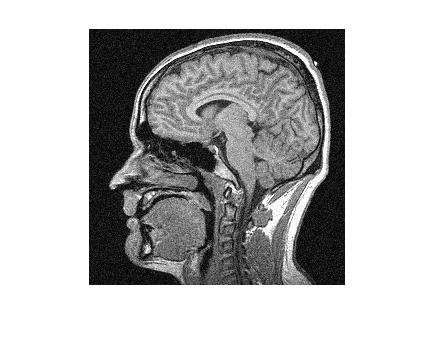

load("brainMRIslice.mat");
imshow(brainMRIsliceNoisy)

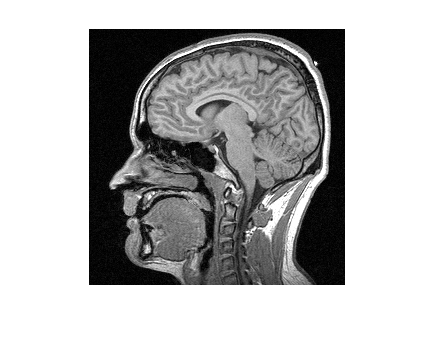

imshow(brainMRIsliceOrig)


% Create indexed image, explicitly using 256 colors
imInd=gray2ind(brainMRIsliceNoisy,256);
% Convert indexed image to RGB using 256-colors jet map
jetRGB=ind2rgb(imInd,jet(256));
% Save image
imwrite(jetRGB,jet,'brainMRINoisy.png')

% Create indexed image, explicitly using 256 colors
imInd=gray2ind(brainMRIsliceOrig,256);
% Convert indexed image to RGB using 256-colors jet map
jetRGB=ind2rgb(imInd,jet(256));
% Save image
imwrite(jetRGB,jet,'brainMRINoiseless.png')

mean = brainMRIsliceNoisy;
alpha = 0.15;
gamma = 0.016;
objective_values=zeros(100);
curr_image = brainMRIsliceNoisy;
iter = 0;
rms(rms(curr_image - brainMRIsliceOrig))/rms(rms(brainMRIsliceOrig))

ans = 0.1424

while true
    iter = iter + 1;
    iter
    temp_image = curr_image;
    for i = 1:256
        for j = 1:256
    
            shift_1 = circshift(curr_image,1,1)-curr_image;
            shift_2 = circshift(curr_image,-1,1)-curr_image;
            shift_3 = circshift(curr_image,1,2)-curr_image;
            shift_4 = circshift(curr_image,-1,2)-curr_image;            
            der_1 = -(1-alpha)*(curr_image(i,j)-mean(i,j));
            der_2 = 0.5*(alpha)*(deriv_quad(shift_1(i,j),gamma) + deriv_quad(shift_2(i,j),gamma)+ deriv_quad(shift_3(i,j),gamma) + deriv_quad(shift_4(i,j),gamma));
            shift(i,j) = 4*(der_1+der_2)/(20+iter);
        end
    end
    curr_image = curr_image + shift;
    rms(rms(curr_image - brainMRIsliceOrig))/rms(rms(brainMRIsliceOrig))
    
    obj=0;
    
    for i = 1:256
        for j = 1:256
            shift_1 = circshift(curr_image,1,1)-curr_image;
            shift_2 = circshift(curr_image,-1,1)-curr_image;
            shift_3 = circshift(curr_image,1,2)-curr_image;
            shift_4 = circshift(curr_image,-1,2)-curr_image;            
            term_1 = (1-alpha)*((curr_image(i,j)-mean(i,j))^2);
            term_2 = (alpha)*(quad(shift_1(i,j),gamma) + quad(shift_2(i,j),gamma)+ quad(shift_3(i,j),gamma) + quad(shift_4(i,j),gamma));
            obj=obj+term_1+term_2;
        end
    end
    
    objective_values(iter)=obj;    
    
    if(rms(rms(shift))<0.001)
        break
    end
end

iter = 1

ans = 0.1323

iter = 2

ans = 0.1271

iter = 3

ans = 0.1244

iter = 4

ans = 0.1230

iter = 5

ans = 0.1223

iter = 6

ans = 0.1220

iter = 7

ans = 0.1218

iter = 8

ans = 0.1217

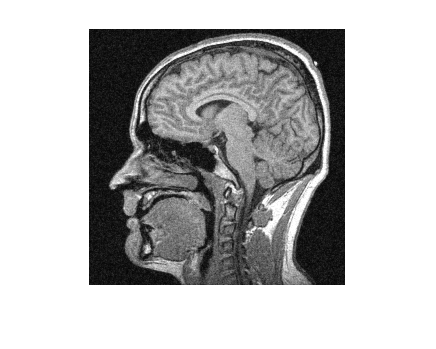

imshow(curr_image);

rms(rms(curr_image - brainMRIsliceOrig))/rms(rms(brainMRIsliceOrig))

ans = 0.1217

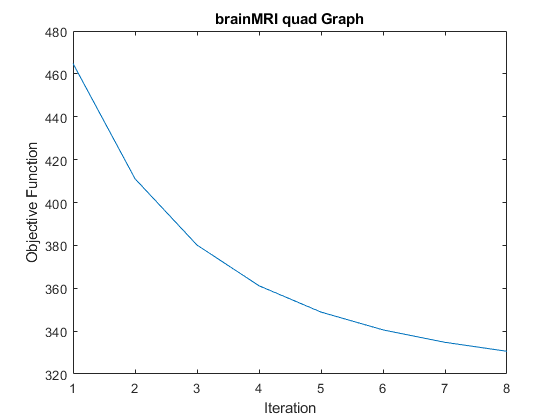


% Create indexed image, explicitly using 256 colors
imInd=gray2ind(curr_image,256);
% Convert indexed image to RGB using 256-colors jet map
jetRGB=ind2rgb(imInd,jet(256));
% Save image
imwrite(jetRGB,jet,'brainMRIquad.png')

figure
plot(1:iter,objective_values(1:iter))
title('brainMRI quad Graph')
xlabel('Iteration')
ylabel('Objective Function')
saveas(gcf,'brainMRI quad Graph.png')

function [derivative] = deriv_DiscontinuityAdaptive(u,gamma)
%Outputs derivative of the DiscontinuityAdaptive function
    modu=abs(u);
    derivative=u*gamma/(gamma+modu);
end

function [derivative] = deriv_Huber(u,gamma)
%Outputs derivative of the Huber function
    modu=abs(u);
    if(modu < gamma)
        derivative=u;
    else
        derivative=gamma*(u/modu);
    end
end

function [derivative] = deriv_quad(u,~)
%Outputs derivative of the Quadratic function
    derivative = 2*u;
end

function [value] = quad(u,~)
%quad function
    value=u^2;
end

function [value] = Huber(u,gamma)
%Huber function
    modu=abs(u);
    if(modu < gamma)
        value=0.5*u^2;
    else
        value=gamma*modu - 0.5*gamma^2;
    end
end

function [value] = DiscontinuityAdaptive(u,gamma)
%DiscontinuityAdaptive function
    modu=abs(u);
    value=gamma*modu - (gamma^2)*log(1+(modu/gamma));
end